**Author: [[Enter Your Full Name Here]]**

***When you are done, Save->Export to PDF. Upload PDF file and your other exam files on Blackboard.***

## Simulate the system with default parameters

Consider the following dynamical system:

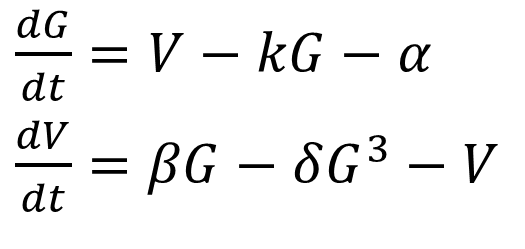

where of V and G are two species whose concentrations change over time as governed by these differential equations; and the system parameters have the following default values: $\alpha \;=1,\;\;\beta \;=1\ldotp 5,\;\;\delta \;=0\ldotp 1,\;k=0\ldotp 2$**. **

Simulate this model with the default parameters and the **default initial values G= -2, V=2. **Show the concentrations of V and G over time (0 to 15 seconds) on the same plot. You may use the provided diff_exam_ahmet2(T,[G0 V0]) function with a -10% penalty to your grade; or create your own derivative function to avoid that penalty.

bmes.diskusage;
%baseurl='https://sacan.biomed.drexel.edu/lib/exe/fetch.php?rev=&media=course:sim2:exam.20233b.th9bx:';
%bmes.downloadurl([baseurl 'diff_exam_ahmet2.p'],'./diff_exam_ahmet2.p');











## Draw the nullclines

Draw the nullclines diagram for this system. You need to decide for yourself, which of the G or V to use as independent variable (ie. x axis of your plot). Your plot should be representative and should have all fixed points in view. You do **not **need to mark the fixed points on the nullclines figure.

## Draw the phase diagram (on top of the nullclines figure)

Display phase diagram quivers on top of the nullcline diagram.

## Draw example integral curves (on top of the nullclines and phase diagram figure)

Run an example simulations with default parameters and with the default initial conditions on top of the nullclines & phase diagram figure. 

Run another example simulation with default parameters and with initial conditions of your choice, on top of the same figure. The initial conditions you choose must demonstrate a fixed point (converge to it or diverge from it), different than the fixed point demonstrated by the default parameters.

Use LineWidth=2 so the integral curves can be easily distinguished.

## Find the fixed point values of V & G analytically (strongly recommended) or numerically

What are the fixed points for the default parameters? Your output must print the values for the fixed points. Fill in only one of the following "analytically" or "numerically" sections. If you fill in both, your analytical solutions will be used for grading.

### If you are solving analytically (recommended):

Use Matlab's symbolic math engine to identify the fixed points. Ignore and remove imaginary solutions, if any. Consider a number imaginary, if the magnitude of the imaginary part is greater than 0.0001. If the magnitude of the imaginary part is less than 0.0001, set the imaginary part to zero. Hint: imag(), real().

### If you are solving numerically:

Run simulations with different initial conditions in order to identify the fixed points. You must identify all stable fixed points by choosing initial conditions carefully.

## Bifurcation Diagram on the parameter beta

Show the fixed point values of G only, for varying levels of beta. Other parameters should be kept at their default values. Vary the levels of beta by the following vector: [0:0.1:2]. Do not show any quiver arrows on your diagram. Only show the fixed point values of G. You may find the fixed points of G for each value of beta analytically or numerically. If you use analytical solutions, handle any imaginary fixed points as described above. If you use numerical solutions, ensure that all stable fixed points are discovered.

## Parameter Optimization

Consider an extended model described by the following differential equations:

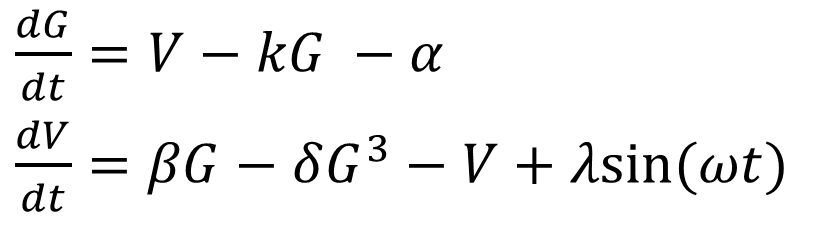	

which includes the additional paramters $\lambda, \omega$ whose values are unknown. You are asked to estimate the values of  $\lambda, \omega$ from experimental data. The experimental data is available in the file experimentaldata.txt.

%bmes.downloadurl([baseurl 'diff_exam_extended_ahmet2.p'],'./diff_exam_extended_ahmet2.p');
%datafile = bmes.downloadurl([baseurl 'experimentaldata2.txt'],'experimentaldata2.txt')
datafile='./experimentaldata2.txt'

datafile = './experimentaldata2.txt'

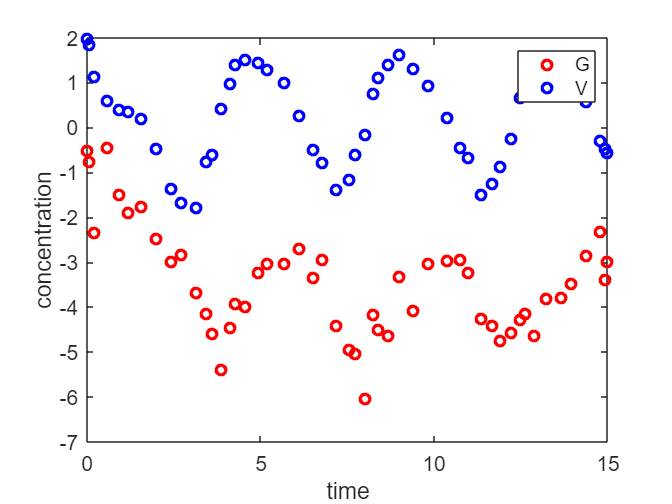

t=readtable(datafile);
plot(t.time, t.G, 'ro', t.time,t.V,'bo', 'LineWidth',2);
legend({'G','V'}); xlabel('time'); ylabel('concentration')

Identify the parameters  $\lambda, \omega$ that best replicate the experimental data. Assume the other parameters and the initial concentrations used in this experiment are the same as the default values listed above. Print the values of the best $\lambda, \omega$ parameters you find, along with the error they achieve. 

A derivative function that implements this system is provided for you as diff_exam_extended_ahmet2(T,Y, params), where **Y is [G,V], **params input is a vector of parameters **[alpha,beta,delta, k, lambda,omega]**. You may use this derivative function (without any penalties to your grade), or create your own.

You may use any optimization approaches and repeat optimization with different random guesses.

Consider using a faster ode solver function with a bigger time step, so the optimization runs faster. If you use a solver that you wrote previously, provide a copy of the solver function in this folder. If you are running an optimization procedure multiple times, consider customizing the optimization tolerance values to have the optimization procedure converge faster.

### Plot best-fit simulation vs. experimental data

Using the bestparameters and initial conditions you found above, now rerun the simulation with these optimized values. Plot the simulation data and experimental data on the same figure. Show experimental data as points (no lines connecting the points), and the simulation data as a line plot.